clear; close all;

[ProgressClassFile, ProgressClassFolder, tf] = uigetfile("F:\YuLab\Work\GPS\Data\*.mat");
if ~tf
    return;
end
ProgressClassPath = fullfile(ProgressClassFolder, ProgressClassFile);

load(ProgressClassPath);

FigFolder = fullfile(ProgressClassFolder, "TestFigs");
if ~isfolder(FigFolder)
    mkdir(FigFolder);
end


Beh = obj.BehavTable;
FP = obj.MixedFP;
Doses = [1/4 1/16 1/64 1/256];


session_chemo = cell(1, length(Doses));
session_control = cell(1, length(Doses));

for i = 1:length(Doses)

    session_chemo{i} = obj.Sessions(obj.Label=="Chemo" & obj.Dose==Doses(i));
    session_control{i} = obj.Sessions(find(obj.Label=="Chemo" & obj.Dose==Doses(i))-1);

end


id_chemo = cell(length(Doses), 2);
id_control = cell(length(Doses), 2);

for i = 1:length(Doses)
    for p = 1:2
        id_chemo{i, p} = find(ismember(Beh.SessionDate, session_chemo{i}) & Beh.Cued==0 & Beh.PortCorrect==p);
        id_control{i, p} = find(ismember(Beh.SessionDate, session_control{i}) & Beh.Cued==0 & Beh.PortCorrect==p);
    end
end


pdf_control = cell(length(Doses), 2);
pdf_chemo = cell(length(Doses), 2);
pdf_control_ci = cell(length(Doses), 2);
pdf_chemo_ci = cell(length(Doses), 2);

bins = 0:0.001:3;
band_width = 0.1;
n_boot = 1000;
valid = 0;

kde_pdf = @(x) ksdensity(x, bins, 'Function', 'pdf', 'Bandwidth', band_width);

for d = 1:4
    for p = 1:2

        disp([d p]);

        data_control = Beh.HoldDuration(id_control{d, p});
        data_chemo = Beh.HoldDuration(id_chemo{d, p});
        switch valid
            case 1
                data_control = data_control(data_control>0.5);
                data_chemo = data_chemo(data_chemo>0.5);
        end

        pdf_control{d, p} = kde_pdf(data_control);
        pdf_chemo{d, p} = kde_pdf(data_chemo);
        pdf_control_ci{d, p} = bootci(n_boot, {kde_pdf, data_control}, 'type', 'cper');
        pdf_chemo_ci{d, p} = bootci(n_boot, {kde_pdf, data_chemo}, 'type', 'cper');

    end
end

     1     1
     1     2
     2     1
     2     2
     3     1
     3     2
     4     1
     4     2


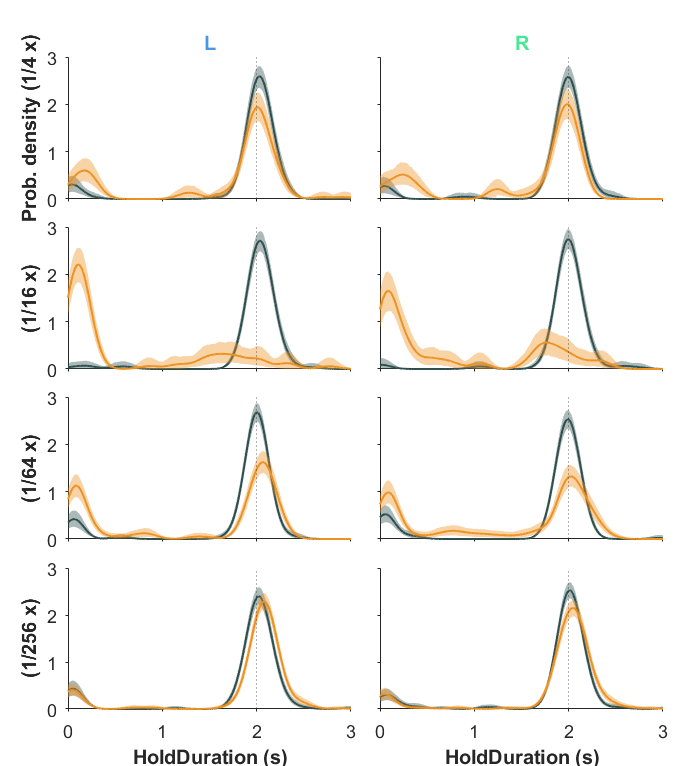

fig = figure(34); clf(34);
set(fig, 'Visible', 'on', 'Units', 'centimeters', 'Position', [5 5 12 13.5], 'Color', 'w');

ax = cell(4,2);

for d = 1:4
    for p = 1:2
        ax{d, p} = axes(fig, 'Units', 'centimeters', 'Position', [1.2+(p-1)*5.5 10-(d-1)*3 5 2.5], 'NextPlot', 'add', 'FontSize', 9, 'TickDir', 'out');

        xline(ax{d, p}, FP, 'LineWidth', .5, 'LineStyle', ':');
        fill(ax{d, p}, [bins flip(bins)], [pdf_control_ci{d, p}(1,:) flip(pdf_control_ci{d, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Control, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax{d, p}, bins, pdf_control{d, p}, ...
            'color', GPSColor.Control, 'linewidth', 1, 'LineStyle', '-');
        fill(ax{d, p}, [bins flip(bins)], [pdf_chemo_ci{d, p}(1,:) flip(pdf_chemo_ci{d, p}(2,:))], 'y', ...
            'FaceColor', GPSColor.Treat, 'FaceAlpha', 0.4, 'EdgeColor', 'none');
        plot(ax{d, p}, bins, pdf_chemo{d, p}, ...
            'color', GPSColor.Treat  , 'linewidth', 1, 'LineStyle', '-');

        if d==1
            ax{d, p}.Title.String = obj.Ports(p);
            ax{d, p}.Title.FontWeight = "bold";
            ax{d, p}.Title.Color = GPSColor.("Port"+obj.Ports(p));
        end
        if d==4
            ax{d, p}.XLabel.String = "HoldDuration (s)";
            ax{d, p}.XLabel.FontWeight = "bold";
        else
            ax{d, p}.XTickLabel = [];
        end
        if p==1
            if d==1
                ax{d, p}.YLabel.String = sprintf("Prob. density (1/%d x)", 1/Doses(d));
            else
                ax{d, p}.YLabel.String = sprintf("(1/%d x)", 1/Doses(d));
            end
            ax{d, p}.YLabel.FontWeight = "bold";
        else
            ax{d, p}.YTickLabel = [];
        end

        drawnow;
    end

end

ax{1,1}.YLim(2) = max(max(cellfun(@(x) x.YLim(2), ax)));
ax{1,1}.YLim(2) = .5 * (ceil(ax{1,1}.YLim(2)) + round(ax{1,1}.YLim(2)));

for d = 1:4
    for p = 1:2
        ax{d, p}.YLim(2) = ax{1,1}.YLim(2);
    end
end

switch valid
    case 0
        fig_name = sprintf("Test_%s_Dose_Timing_%s.jpg", obj.Task, obj.Subject);
    case 1
        fig_name = sprintf("Test_%s_Dose_Timing_valid_%s.jpg", obj.Task, obj.Subject);
end
fig_path = fullfile(FigFolder, fig_name);
exportgraphics(fig, fig_path, 'Resolution', 600);